# How to create a publication-quality figure using Matlab

## Motivation

As humans are highly visual, good-looking figures may increase the chance that your paper look good and thus get accepted by a journal with higher impact-factor. Here I summarize tips to transform your nothing-but-ordinary figures into publication-quality ones.

## (Before formatting) Preparing a figure

Here we consider a scatter plot with a linear regression line as an example. It looks as follows:

% create an example scatter plot with a linear regression line ------------
% data generation
rng(20180301)
x = rand(30, 1);
y = 0.6*x + 0.4*rand(30, 1);

% Spearman correlation
[r_corr, p_corr] = corr(x, y, 'type', 'Spearman');

% linear regression
b = glmfit(x, y, 'normal', 'link', 'identity', 'constant', 'on');

% Wilcoxon rank sum test
p = ranksum(x,y);


% plot unity line
plot(xrange, yrange, '-', 'color', 0.4*ones(1,3),'linewidth', 0.5)
hold on;


% plot the regression line
xrange = [0, 1];
plot(xrange, glmval(b, xrange, 'identity'), '-r', 'linewidth', 0.5)
hold on;

% create a figure
scatter(x, y, 30, 'markerfacecolor', 'r', 'markerfacealpha', 0.4, ...
    'markeredgecolor', 'w', 'markeredgealpha', 0.8)
hold on;

% formatting axis
yrange = xrange;
text(0.6*xrange(2), 0.2*yrange(2), ['rho=' num2str(r_corr) ', p=' num2str(p_corr)])
text(0.6*xrange(2), 0.1*yrange(2), ['ranksum: p=' num2str(p)])
xlim(xrange)
ylim(yrange)
xlabel('x')
ylabel('y')
title('my data')

## General formatting tips

A figure looks typically better when:

- ticks are oriented outside

- box is off

- axis is square

- Fonts are same across all the labels and texts (Font size of 6 is a nice choice basically for many journals)

- Tick labels at most 3 in each axis

These can be achieved easily as follows:

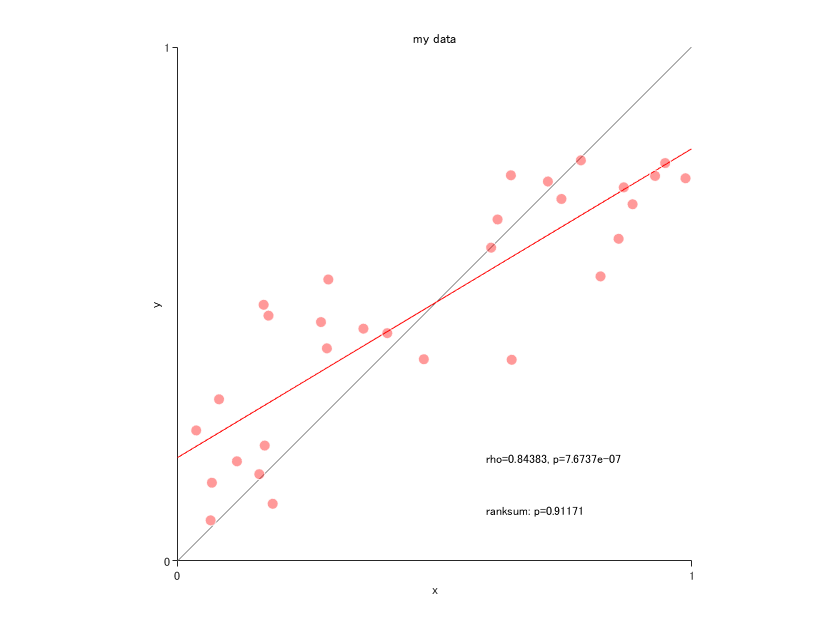

% ticks orienting outward
set(gca, 'TickDir', 'out')

% box off
set(gca, 'box', 'off')

% square axis
axis square

% same font size (this time 6)
set(findall(gcf, '-property', 'FontSize'), 'FontSize', 6)

% two tick-labels in each axis
set(gca, 'XTick', xrange)
set(gca, 'YTick', yrange)

## Copy axes 

Typically there are multiple figures.

figPars.Color =         'w';
figPars.Units =         'centimeters';
figPars.PaperUnits =    'centimeters';

% since 2014b 
axPars.xcolor = 'k';
axPars.ycolor = 'k'; 

axPars.TickDir =        'out';
axPars.TickLength =     [0.02 0.02];
axPars.Box =            'off';
axPars.Units = 'centimeters';
axPars.FontName=  'Arial';

switch type
    case 'paper'
        axPars.FontSize     = 6; %formerly 8
        axPars.LineWidth    = 0.5;
    case 'poster'
        axPars.FontSize     = 24;
        axPars.LineWidth    = 2;
    case 'slide'
        axPars.FontSize =       10;
        axPars.LineWidth =       1;
    case 'otherwise'
        error('<setPlotPars> Unknown plot type');
end

## Introduce offset axis

h = gca;
%shift_percentage = 0.2;0.05;

box off
axis off

if length(shift_percentage)==2
        xshift_percentage = shift_percentage(1);
        yshift_percentage = shift_percentage(2);
elseif length(shift_percentage)==1
        xshift_percentage = shift_percentage;
        yshift_percentage = shift_percentage;
end
        

base_pos = get(h,'position');

expos_1 = base_pos;
expos_1(1) = expos_1(1)-expos_1(3)*xshift_percentage;
% set(a,'xlim',[-110 220]);
% set(a,'ylim',[-0 2.5]);
% set(b,'xlim',[-110 220]+bkmask_delay);




expos_1(3) = 1/10^10;
a1=axes(axPars,'position', expos_1);
expos_2 = base_pos;
expos_2(2) = expos_2(2) - expos_2(4)*yshift_percentage;
expos_2(4) = 1/10^10;
a2=axes(axPars,'Position', expos_2);



set(a2,'xtick',get(h,'xtick'),'xticklabel',get(h,'xticklabel'))
set(a2,'xlim',get(h,'xlim'))
set(a2,'xlabel',get(h,'xlabel'))
set(a2,'ticklength',[0.02 0.02])

set(a1,'ytick',get(h,'ytick'),'yticklabel',get(h,'yticklabel'))
set(a1,'ylim',get(h,'ylim'))
set(a1,'ylabel',get(h,'ylabel'))
set(a1,'ticklength',[0.02 0.02])
% set(a2)